# Using Bernstein-Vazirani Algoirthm to Attack Block Ciphers

The Bernstein-Vazirani (BV) algorithm [1] is a well known quantum algorithm that can solve certain problems with a linear speedup, In this example we will use the BV algorithm to attack blocks ciphers, expoloting it's reduced complexity compared to classical algorithm.

First we will see the problem that the BV algorithm solves and use a classical approach to find the solution, than we will build a generic circuit to implement the algorithm and lastly we will build a specific algoithm in order to attack the Even-Mansour cipher

## The Problem

Let $f:{\left\lbrace 0,1\right\rbrace }^n \to \left\lbrace 0,1\right\rbrace$be a function of the form:


$$f\left(x\right)=s\cdot x\;\;\;\;\textrm{mod2}$$


where $x\in {\left\lbrace 0,1\right\rbrace }^n \;$is an n-bit input, $s\in {\left\lbrace 0,1\;\right\rbrace }^n \;$is a hidden string of n bits and the operation $s\cdot x$ denotes the dot product modulo 2 defined as:


$$s\cdot x=s_0 x_0 \oplus s_1 x_1 \oplus \cdots \oplus s_{n-1} x_{n-1}$$


where $\oplus$ is a bitwise XOR.

find $s$.

## Classical Solution

with a classical computer the fastest way to find s is to evaluate $f\left(x\right)\;$n time with input values $x=2^i$ for each $i\in \left\lbrace 0,1,\;\cdots \;,n\;-1\;\right\rbrace$:


$$\begin{array}{l}
f\left\lbrace 100\cdots 0_n \right\rbrace =s_1 \\
f\left\lbrace 010\cdots 0_n \right\rbrace =s_2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\vdots \;\\
f\left\lbrace 000\cdots 1_n \right\rbrace =s_n 
\end{array}$$


making the complexity of the algorithm obviusly $O\left(n\right)$.

let's see an example with a 5 digit input

## Solving Using Bernstein-Vazirani Quantum Algorithm

#### Initialization

Using the Bernstein-Vazirani algorithm will allow us to obtain a linear speedup and solve the probelem with only one query to the oracle $U_f$.

The quantum circuit must have a register with n qubits to rappresent the input values $x$ and a single qubit register to store the result $f\left(x\right)$, we are gonna set the initial state of the circuit this way:


$$|\psi_o \rangle =|0\rangle^{\otimes n} \;|1\rangle$$


#### Explaining the Circuit

after applying an Hadamard transorm to both the input register and the result register the state becomes


$$|\psi_1 \rangle =\sum_{x\in {\left\lbrace 0,1\right\rbrace }^n }^{2^n -1} \frac{|x\rangle }{\sqrt{2^n }}\;\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


the input register is now a superposition of all values and the result register is in a superposition of 0 and 1. next the function $f$ is evaluated by the oracle $U_f :|x,y\rangle \to |x,y\oplus f\left(x\right)\rangle$ giving


$$|\psi_2 \rangle =\sum_x^{2^n -1} \frac{{\left(-1\right)}^{f\left(x\right)} |x\rangle }{\sqrt{2^n }}\;\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


it is clear from this formula that now the information about $f\left(x\right)\;$is stored in the amplitude. Finally after applying anothe Hadamard transform on the input register we get the form

$|\psi_3 \rangle =\sum_z^{2^n -1} \sum_x^{2^n -1} \frac{{\left(-1\right)}^{x\cdot z+f\left(x\right)} |z\rangle }{2^n }$$\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$= $\sum_z^{2^n -1} \sum_x^{2^n -1} \frac{{\left(-1\right)}^{x\cdot z+x\cdot s} |z\rangle }{2^n }$$\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$

now let's analyze just the term $\sum_x \frac{{\left(-1\right)}^{x\cdot z+x\cdot s} |z\rangle }{2^n }$, $x\cdot z+x\cdot s=0$  if and only if $z=s$, so $|\psi_3 \rangle =|s\rangle$ with probability of mesurement 1, while each and every other combination having $x\cdot z+x\cdot s=0$ has a probability to be mesured equal to zero. So with one single query to the oracle we obtained the secret string $s$. 

Here you can see the oracle in it's whole:

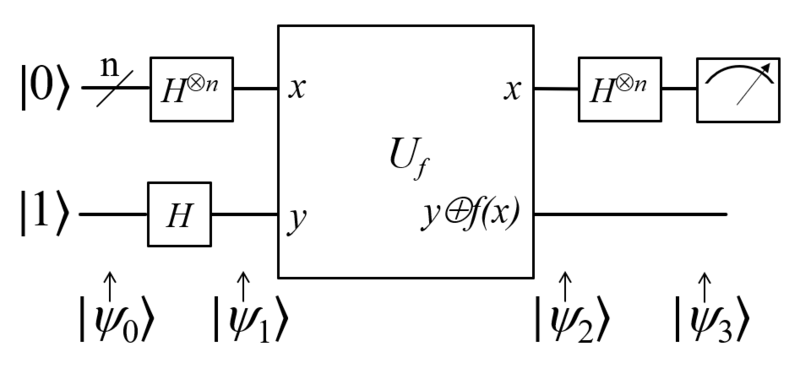

#### Building the Circuit

now let's implement our circuit with an oracle specific to $s$ and test it

function qc = BVcircuit(numQubits, secret_string)
    totalQubits = numQubits + 1;

    gates = [];

    gates = [gates, xGate(numQubits+1)];

    % apply Hadamard gate on each qubit
    for n = 1:totalQubits
        gates = [gates, hGate(n)];
    end

    % create oracle
    for(n = 1:totalQubits-1)
        if secret_string(n) == '1'
            gates = [gates, cxGate(n, totalQubits)];
        end
    end

    % apply Hadamard on the input register
    for n = 1:numQubits
        gates = [gates, hGate(n)];
    end

    qc = quantumCircuit(gates, numQubits + 1); 
    
end

Select the specific secret string $s$ and the function will automatically implement the amount of qubits required

secret_string = char("1010111");

Keep in mind that $s$ will not be use to fine the result, but just to implement it's specific oracle!

numQubits = length(secret_string);
qc = BVcircuit(numQubits, secret_string);

now let's plot the circuit

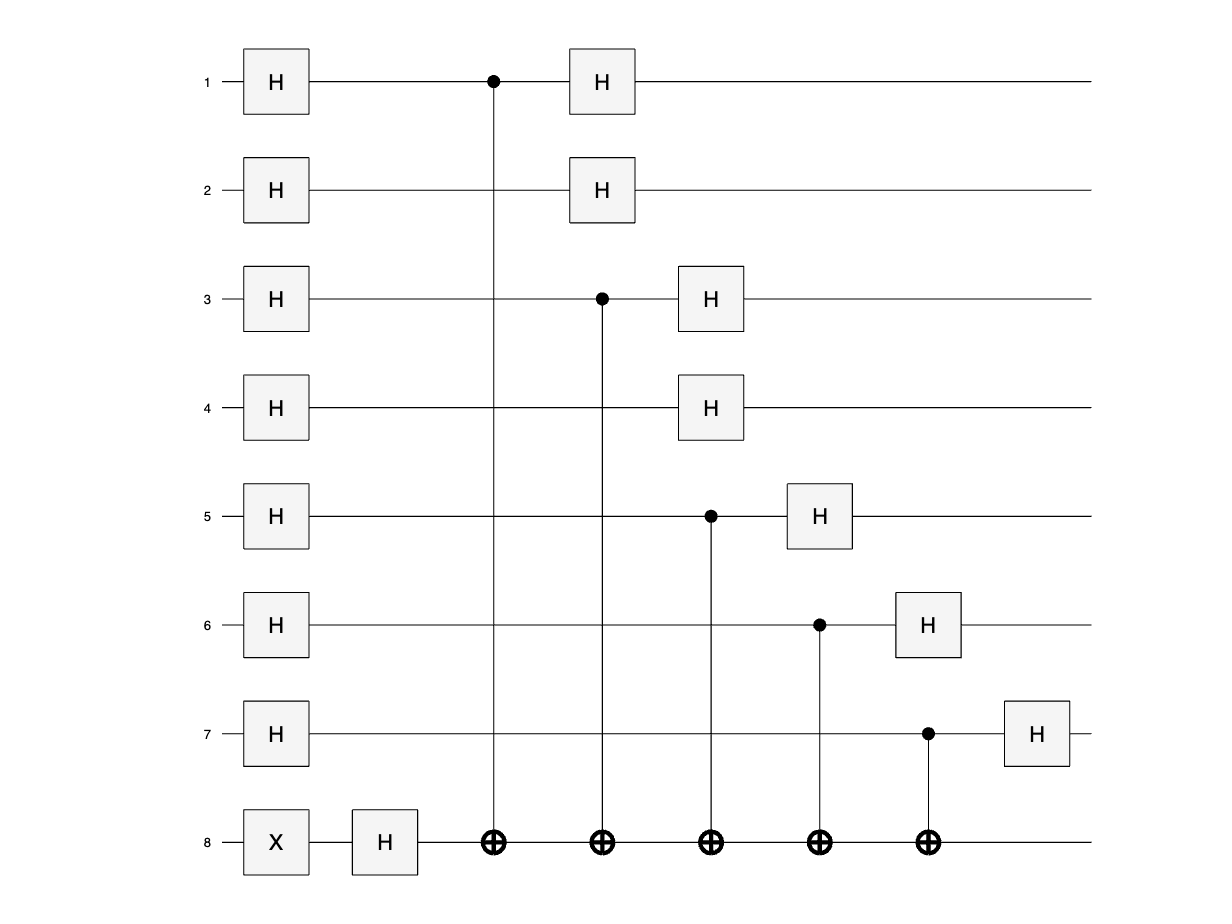

plot(qc);

finally, let's simulate the circuit and see the results

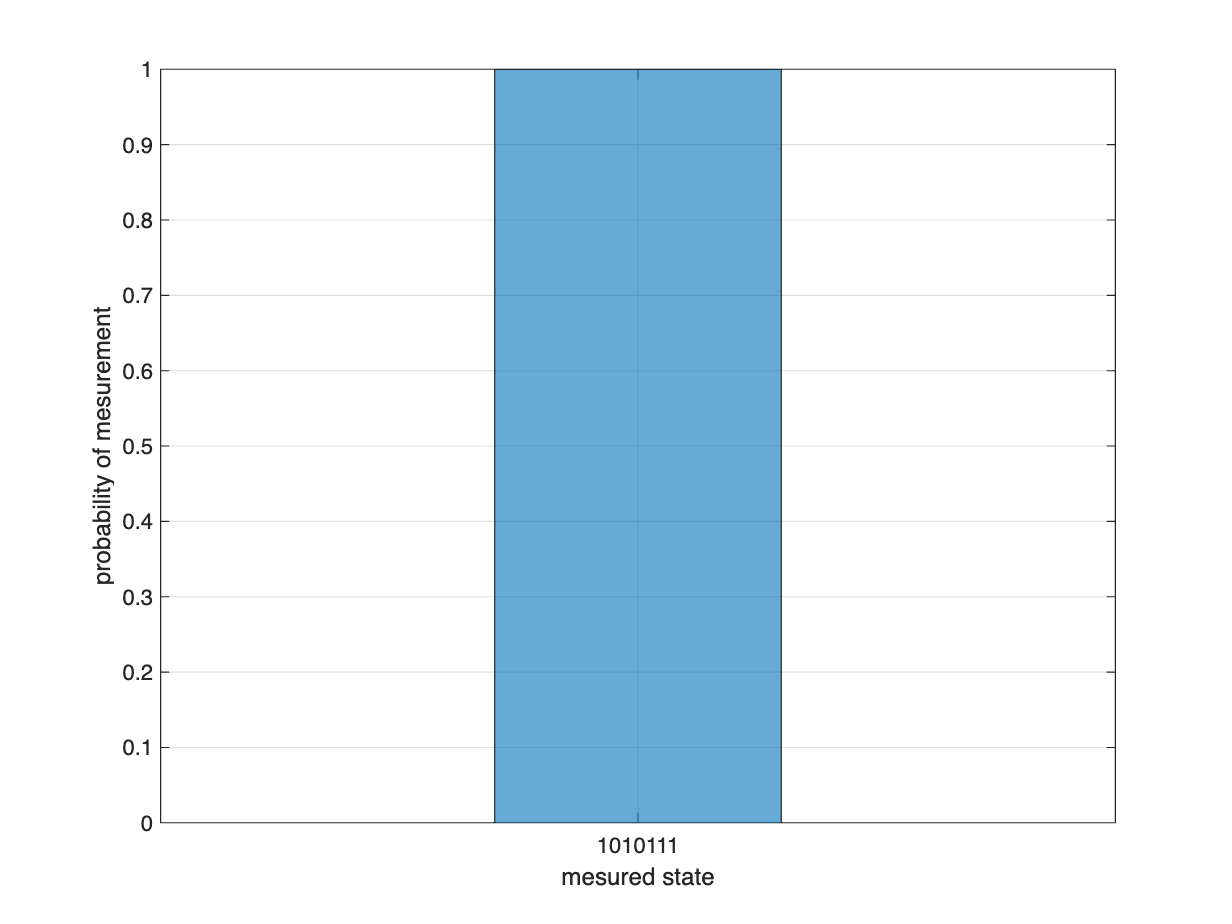

s = simulate(qc);

histogram(s, 1:numQubits);
xlabel('mesured state');
ylabel('probability of mesurement');
grid on;

as expected we mesure the sting $s$ with probability 1 with only one query to the oracle ($O\left(1\right)$), offering a linear speedup compared to the classical solution ($O\left(n\right)$)

## The Even-Mansour Cipher

It has been proven [2] that the Bernstein Vazirani algorithm (and Simon's Algoithm [3]) can be exploited to break block ciphers such as the Even-Mansour (EM) Cipher [4].

in this figure you can see the Even-Mansour cipher

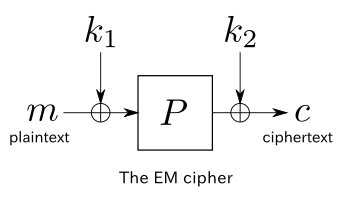

The cipher can be seen as a function:

 
$$E_k \left(m\right)=P\left(m\oplus k_1 \right)\oplus k_2$$
 

where $k_1$and $k_2$ are the secret keys, $P$ is a public permutation, $m$ is the plaintext and $c$ is the ciphertext

## Attackig the Even-Mansour Cipher with Bernstein Vazirani Algoithm

For the porpuse of this example we are just going to implement the algoithm to find $k_1$, show the results and it's reduced complexity, to understand the mathematical theory behind this you can read the original paper [1] by H. Xie and L. Yang for a complete and formal explanation, the algorithm we are going to implement is algorithm 4 of the paper.

this is an example of a single iteration to the quantum circuit we are going to use for the main algoithm, feel free to change the input parameters as you please

function qc = BVAttackEvenMansourCircuit(k1, k2, perm, iter)
% Single Bernstein–Vazirani circuit for component Fj
    n       = length(k1);                % registers size
    ws      = 2*n;                       % workspace size
    totalQ  = n + ws;                    % data + workspace qubits
    anc     = totalQ + 1;                % ancilla register
    gates   = [];                        % gates init

    % 1) prepare |x> in superposition
    for i = 1:n
        gates = [gates, hGate(i)];
    end

    % 2) put ancilla in |->
    gates = [gates, xGate(anc), hGate(anc)];

    % 3) compute F(x) = E_k(x) xor P(x) into workspace
    gates = computeF_EM(gates, n, k1, k2, perm);

    % 4) CNOT from F_j to ancilla
    Fstart = 2*n + 1;                    % workspace index where F starts
    ctrl   = Fstart + (iter - 1);        % j-th bit of F
    gates  = [gates, cxGate(ctrl, anc)];

    % 5) uncompute workspace
    gates = uncomputeF_EM(gates, n, k1, k2, perm);

    % 6) final Hadamard transform on data qubits
    for i = 1:n
        gates = [gates, hGate(i)];
    end

    qc = quantumCircuit(gates, totalQ + 1); % build circuit
end

#### Input parameters

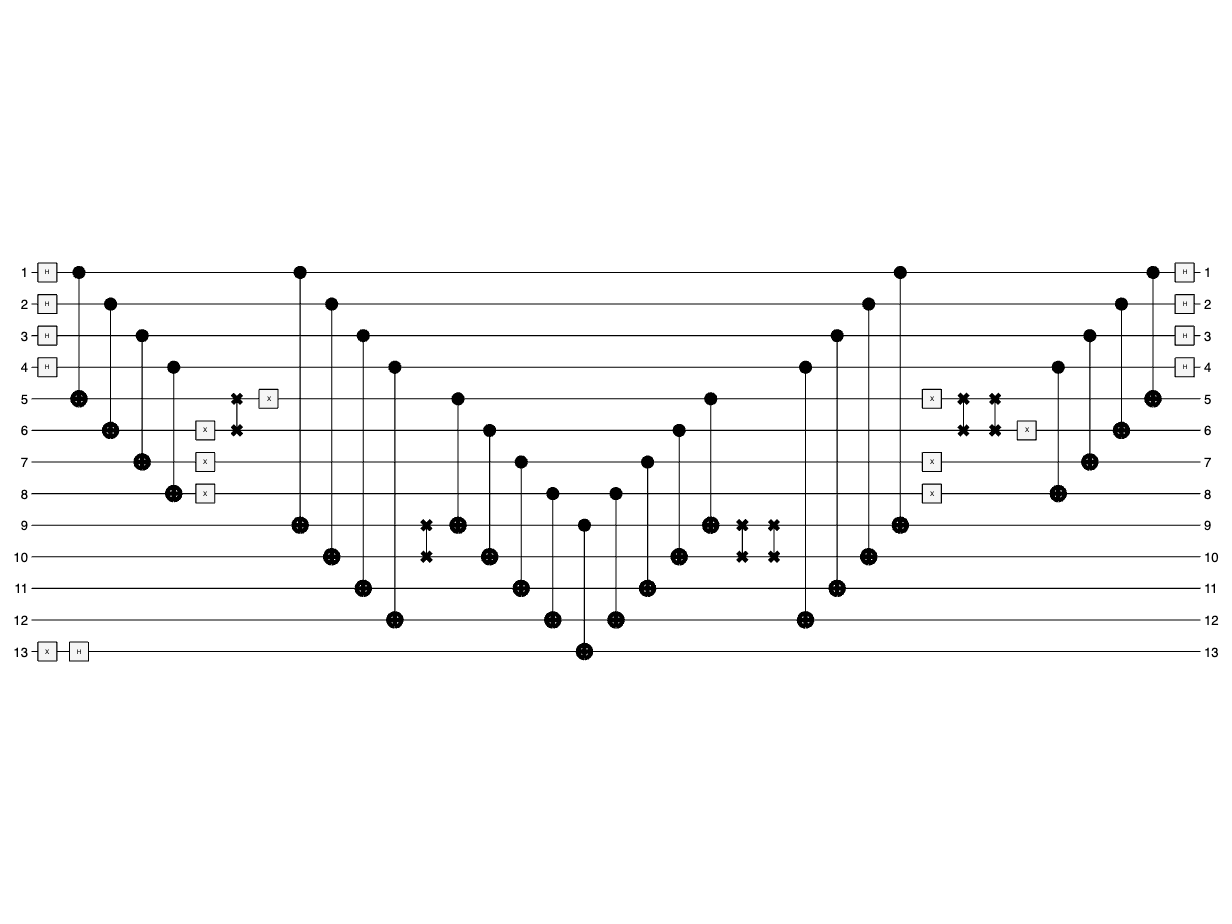

% note that k1 and k2 must be of the same size
% it is also suggested to keep the length of the keys below 7 bits to
% grant fast computartion

k1   = '0101';                 % secret key k1
k2   = '1010';                 % secret key k2
perm = [2 1 3 4];              % public permutation P
qc   = BVAttackEvenMansourCircuit(k1, k2, perm, 1);

plot(qc);

Once we know how to create the oracle we can build the actual algorithm to find $k_1$

%% -----------------------  ATTACK CONFIGURATION  --------------------------------
% note that k1 and k2 must be of the same size
% it is also suggested to keep the length of the keys below 7 bits to
% grant fast computartion
k1   = '01110';                 % secret key k1
k2   = '11001';                 % secret key k2
perm = [2 1 3 4 5];              % public permutation P
p    = 3 * length(k1);         % ≥ 2*n BV runs per Fj to reduce error probability

%% -----------------------  MAIN ATTACK  ----------------------------------
n     = length(k1);             % input size
candS = [];                     % progressive intersection of candidates

for j = 1:n
    H = zeros(p, n);            % will store the results for Fj

    for t = 1:p                 % --- inner BV loop ---
        qc     = BVAttackEvenMansourCircuit(k1, k2, perm, j);   % build scircuit for specific iteration
        sample = randsample(simulate(qc), 1);                   % single shot
        bits   = char(sample.MeasuredStates);
        H(t,:) = bits(1:n) == '1';                              % add result to results set
    end

    Aj = solve_homogeneous(H);   % solve the system of linear equations

    if j == 1
        candS = Aj;              % initialise if is the first iteration of the main loop
    else
        candS = intersect(candS, Aj, 'rows');   % set intersection if not the first iteration
    end
end

%% -----------------------  RESULT  ---------------------------------------
fprintf('\nFinal candidates: (should only be the trivial solution and k1):\n');


Final candidates: (should be only the trivial solution and k1):


disp("number of results: " + length(candS)), disp(candS);

number of results: 16
     0     0     0     0     0
     0     0     0     0     1
     0     0     0     1     0
     0     0     0     1     1
     0     0     1     0     0
     0     0     1     0     1
     0     0     1     1     0
     0     0     1     1     1
     1     1     0     0     0
     1     1     0     0     1
     1     1     0     1     0
     1     1     0     1     1
     1     1     1     0     0
     1     1     1     0     1
     1     1     1     1     0
     1     1     1     1     1



From a simple analysis it's clear that the complexty of this algorithm, due to the two nested loops, amoutns to $O\left(n^2 \right)$, while a classical computer could do the same task only with a complexity of $O\left(2^{\frac{n}{2}} \right)$as shown is [4].

### Helper functions:

here you can find the functions used to compute che oracle and solve the system of linear equations after each iteration of the main algoithm loop

#### Solves the system of linear equations

function A = solve_homogeneous(M)
% brute force, ok for small keys
    M = mod(M,2);
    [~, n] = size(M);
    sols = [];
    for x = 0:(2^n - 1)
        v = dec2bin(x, n) == '1';
        if all(~mod(M * v', 2)), sols = [sols; double(v)]; end
    end
    A = unique(sols, 'rows');
end

#### Computes $E_k \left(m\right)=P\left(m\oplus k_1 \right)\oplus k_2 \oplus P\left(m\right)$ in the quantum cicuit

function gates = computeF_EM(gates, n, k1, k2, perm)

% computation of F(x) = E_k(x) xor P(x)
    Epos = n + 1;            % workspace block for E_k(x)
    Ppos = Epos + n;         % workspace block for P(x)

    gates = computeE(gates, n, Epos, k1, k2, perm); % compute E_k(x) on the first support register
    gates = computeP(gates, n, Ppos, perm);         % compute P(x) on the second support register
    for j = 0:n-1
        gates = [gates, cxGate(Epos+j, Ppos+j)];   % P(x) xor E_k(x) = P(x) xor P(x xor k1) xor k2
    end
end

#### Uncomputes $E_k \left(m\right)=P\left(m\oplus k_1 \right)\oplus k_2 \oplus P\left(m\right)$ in the quantum cicuit

function gates = uncomputeF_EM(gates, n, k1, k2, perm)

% uncomputation of F(x) = E_k(x) xor P(x)
    Epos = n + 1;  Ppos = Epos + n;
    for j = n-1:-1:0
        gates = [gates, cxGate(Epos+j, Ppos+j)];
    end

    gates = uncomputeP(gates, n, Ppos, perm);
    gates = uncomputeE(gates, n, Epos, k1, k2, perm);
end

#### Computes $E_k \left(m\right)=P\left(m\oplus k_1 \right)\oplus k_2$ in the quantum cicuit

function gates = computeE(gates, n, out, k1, k2, perm)

    % copy x in support register
    for j = 1:n
        gates = [gates, cxGate(j, out+j-1)];
    end

    % xor k1
    for j = 1:n
        if k1(j)=='1'
            gates=[gates, xGate(out+j-1)]; 
        end
    end

    % permutation P
    cur = 1:n;
    for j = 1:n
        p = perm(j);
        if p ~= cur(j)
            gates = [gates, swapGate(out+j-1, out+p-1)];
            cur(cur==p) = cur(j);  cur(j) = p;
        end
    end

    % xor k2
    for j = 1:n
        if k2(j)=='1'
            gates=[gates, xGate(out+j-1)];
        end
    end
end

#### Unomputes $E_k \left(m\right)=P\left(m\oplus k_1 \right)\oplus k_2$ in the quantum cicuit

function gates = uncomputeE(gates, n, out, k1, k2, perm)

    % xor k2
    for j = n:-1:1
        if k2(j)=='1', gates=[gates, xGate(out+j-1)];
        end
    end

    cur = perm;
    % permutation P
    for j = n:-1:1
        p = find(cur == j);
        if p ~= j
            gates = [gates, swapGate(out+j-1, out+p-1)];
            cur(cur==p) = cur(j);  cur(j) = p;
        end
    end

    % xor k1
    for j = n:-1:1
        if k1(j)=='1'
            gates=[gates, xGate(out+j-1)];
        end
    end

    for j = n:-1:1
        gates = [gates, cxGate(j, out+j-1)];
    end
end

#### Computes $P\left(m\right)\;$in the quantum circuit

function gates = computeP(gates, n, out, perm)
    % copy on register
    for j = 1:n
        gates = [gates, cxGate(j, out+j-1)];
    end

    % permutation P
    cur = 1:n;
    for j = 1:n
        p = perm(j);
        if p ~= cur(j)
            gates = [gates, swapGate(out+j-1, out+p-1)];
            cur(cur==p) = cur(j); cur(j) = p;
        end
    end
end

#### Uncmputes $P\left(m\right)\;$in the quantum circuit

function gates = uncomputeP(gates, n, out, perm)
    cur = perm;
    for j = n:-1:1
        p = find(cur == j);
        if p ~= j
            gates = [gates, swapGate(out+j-1, out+p-1)];
            cur(cur==p) = cur(j); cur(j) = p;
        end
    end

    for j = n:-1:1
        gates = [gates, cxGate(j, out+j-1)];
    end
end

## References

[[1] E. Bernstein, U. Vazirani. "Quantum Complexity Theory"](https://dl.acm.org/doi/pdf/10.1145/167088.167097)

[[2]](https://link.springer.com/article/10.1007/s10623-018-0510-5) [H. Xie, L. Yang.  "Using Bernstein-Vazirani algorithm to attack block ciphers"](https://link.springer.com/article/10.1007/s10623-018-0510-5)

[[3] H. Kuwakado, M. Morii. "Security on the Quantum-type Even-Mansour Cipher"](https://ieeexplore.ieee.org/document/6400943)

[[4] S. Even, Y. Mansour. "A Construction of a Cipherfrom a Single Pseudorandom Permutation](https://link.springer.com/article/10.1007/S001459900025)"